inputWeights = mlp.IW{1};
inputWeights = sum(abs(inputWeights))

inputWeights =     0.6752    0.8671    1.0285    1.5437    0.6997    0.5374    0.5851    0.4262    0.3692    1.0185    0.4849    1.2069    0.7474    0.8246    0.7990    0.6456    0.9146    1.1620    2.5502    0.6856    0.5162    0.5279    0.5981    0.8838    0.4360    1.3390    2.4953    1.2495    0.9734    0.4656    0.5325    0.5726    1.0911    0.6257    1.0010    0.7845    1.5546    1.0675    0.4879    1.2051    0.7536    1.6436    0.8438    1.3636    1.1027    1.1621    1.4598    1.4097    1.2493    1.6568


[maxWeight, idx] = max(inputWeights);
selectedFeature = features(idx,:)

selectedFeature =     1.2566    4.9276    1.7108    2.8216    1.7337    3.5067    2.0956    4.3422    2.0683    1.3426    2.3608    2.3470    3.3603    2.8626    6.4716    1.9781    3.6855    2.7729    2.4678    2.8682    4.0877    1.9374    1.3271    3.9490    2.9412    3.5246    4.9337    1.8316    3.2702    3.3373    1.8998    1.5418    2.4628    1.1719    2.5492    3.1737    1.5489    3.0212    2.4978    1.7840    2.0624    1.6180    2.2555    4.9595    7.4228    1.5188    2.0700    1.3624    2.5249    2.3436


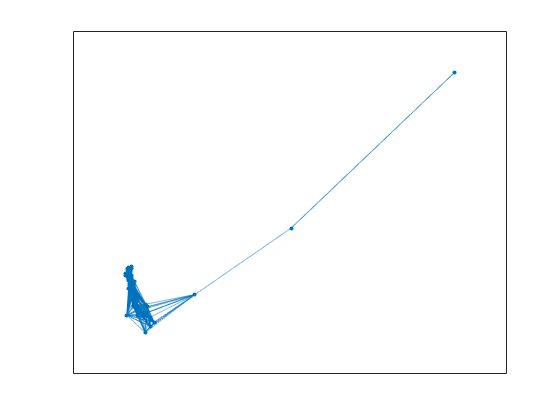

A = zeros(length(selectedFeature));
for i = 1:length(selectedFeature)
    for j = 1:length(selectedFeature)
        A(i,j) = abs(selectedFeature(i) - selectedFeature(j));
    end
end
p = 1;
A = (A<mean(A(:)));
A = A - diag(diag(A));
G = graph(A);
plot(G);

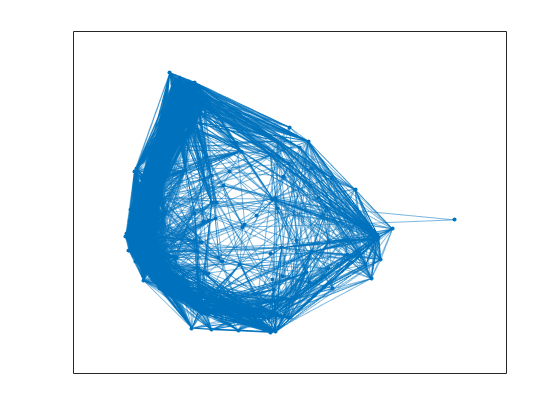

rho = corr(features');
p = 0.16;
rho = rho - diag(diag(rho));
rho = (rho > p);
G = graph(rho, 'upper');
plot(G)